clear 
clc

% Reading input file
% read file from inputPrecipTemp.txt
PTIf=xlsread("C:\Users\Administrator\Desktop\CEE450\data_table5.xlsx");
% The structure of the file is [date,month1,year,month,Temp,prec]
day_list=(1:1:length(PTIf))';
Temp=PTIf(:,9);
prec=PTIf(:,4);
qo=PTIf(:,6);
qf0=PTIf(:,7); % observed fast flow
qs0=PTIf(:,8); % observed slow flow

daily=PTIf(:,5);

dpem=PTIf(:,5);

% Getting the range  for the parameters 


ddl=3; % DD lb
fcl=100; % FC lb
betal=1; % Beta lb
cl=0.01; % C lb
k0l=0.05; % K_0 lb
l1l=2; % L lb
k1l=0.01; % K_1 lb
k2l=0.01; % K_2 lb
kpl=0.01; % K_p lb
pwpl=90; % PWP lb
ddu=7; % DD ub
fcu=200; % FC up
betau=7; % Beta ub
cu=0.07; % C ub
k0u=0.2; % K_0 ub 
l1u=5; % L ub
k1u=0.1; % K_1 ub
k2u=0.05; % K_2 ub
kpu=0.05; % K_p ub
pwpu=180; % PWP ub


tt=6; % Snow Melt Thr T_t
ns=110; % number of simulations
snow(1,1:ns)=300; % initial value Snow
soil(1,1:ns)=100; % initial value Soil Moisture 
s1(1,1:ns)=3; % initial value S_1
s2(1,1:ns)=10; % initial value S_2
in = 2; % Optimization Criteria 

n=size(Temp,1);
aq=mean(qo);
tprec=0;
tea1=0;
reg1=0; %#ok<*NASGU>
nash=0; % Nash Sutcliff 
mqo=sum(qo);

% random generation of values for parameters
d=(rand(ns,1)*(ddu-ddl))+ddl;
fc=(rand(ns,1)*(fcu-fcl))+fcl;
beta=(rand(ns,1)*(betau-betal))+betal;
c=(rand(ns,1)*(cu-cl))+cl;
k0=(rand(ns,1)*(k0u-k0l))+k0l;
l=(rand(ns,1)*(l1u-l1l))+l1l;
k1=(rand(ns,1)*(k1u-k1l))+k1l;
k2=(rand(ns,1)*(k2u-k2l))+k2l;
kp=(rand(ns,1)*(kpu-kpl))+kpl;
pwp=(rand(ns,1)*(pwpu-pwpl))+pwpl;
% end of random generation


% Calculating Q simulated for entered number of simulations
for s=1:ns
    for i=2:n-1
        if(Temp(i)<tt)
            snow(i,s)=snow(i-1,s)+prec(i);
            lwater(i,s)=0;
            pe(i,s)=PTIf(i,5);
            if(soil(i-1,s)>pwp(s))
                ea(i,s)=pe(i,s);
            else
                ea(i,s)=pe(i,s)*(soil(i-1,s)/pwp(s));
            end
            dq(i,s)=lwater(i,s)*((soil(i-1,s)/fc(s))^beta(s));
            soil(i,s)=soil(i-1,s)+lwater(i,s)-dq(i,s)-ea(i,s);
            s1(i,s)=s1(i-1,s)+dq(i,s)-(max(0,s1(i-1,s)-l(s))*k0(s))-(s1(i-1,s)*k1(s))-(s1(i-1,s)*kp(s));
            s2(i,s)=s2(i-1,s)+(s1(i-1,s)*kp(s))-s2(i-1,s)*k2(s);
            q(i,s)=(max(0,s1(i-1,s)-l(s)))*k0(s)+(s1(i,s)*k1(s))+(s2(i,s)*k2(s));
            qm(i,s)=q(i,s);
        else
            snow(i,s)=max(snow(i-1,s)-d(s)*(Temp(i)-tt),0);
            lwater(i,s)=prec(i)+min(snow(i-1,s),d(s)*(Temp(i)-tt));
            pe(i,s)=PTIf(i,5);
            if(soil(i-1,s)>pwp(s))
                ea(i,s)=pe(i,s);
            else
                ea(i,s)=pe(i,s)*(soil(i-1,s)/pwp(s));
            end
            dq(i,s)=lwater(i,s)*((soil(i-1,s)/fc(s))^beta(s));
            soil(i,s)=soil(i-1,s)+lwater(i,s)-dq(i,s)-ea(i,s);
            s1(i,s)=s1(i-1,s)+dq(i,s)-(max(0,s1(i-1,s)-l(s))*k0(s))-(s1(i-1,s)*k1(s))-(s1(i-1,s)*kp(s));
            s2(i,s)=s2(i-1,s)+(s1(i-1,s)*kp(s))-s2(i-1,s)*k2(s);
            q(i,s)=(max(0,s1(i-1,s)-l(s)))*k0(s)+(s1(i,s)*k1(s))+(s2(i,s)*k2(s));
            qm(i,s)=q(i,s);
        end
    end
    mq(s,1)=sum(qm(:,s));
    qo = qo(1:n-1);
    e(:,s)=qo-qm(:,s);% calculating difference between q observed and q measured
    nse(s,1)=1-(sum((e(:,s)).^2))/(sum((qo-aq).^2)); % calculating nse
    qrms(s,1)=sqrt(mean((e(:,s)).^2)); % calculating root mean square value
    regg1(s,1)=corr(qm(:,s),qo);
    tbias(s,1)=mq(s,1)/mqo;
end
nseqm=[nse qm'];

% end of simulation

corr1=regg1;
qrms1=qrms;
nse1=nse;
cb=1-power(tbias,2);
cb1=cb;

% code to get the optimal parameter
if(in==1)
    peako=min(qrms1);%  Calculating minimum of root mean square value to determine optimal parameters
    for p=1:ns
        if(qrms1(p)==peako)
            v=p;% index of optimal parameter
        end
    end
end
if(in==2)
    peako=max(nse1);
    for p=1:ns
        if(nse1(p)==peako)
            v=p;% index of optimal parameter
        end
    end
end
if(in==3)
    peako=max(corr1);
    for p=1:ns
        if(corr1(p)==peako)
            v=p;% index of optimal parameter
        end
    end
end
if(in==4)
    peako=min(cb1);
    for p=1:ns
        if(cb1(p)==peako)
            v=p;% index of optimal parameter
        end
    end
end
cd=d(v)

cd = 6.6175

cfc=fc(v)

cfc = 177.5587

cbeta=beta(v)

cbeta = 6.8389

cc=c(v)

cc = 0.0350

ck0=k0(v)

ck0 = 0.1339

cl=l(v)

cl = 4.4967

ck1=k1(v)

ck1 = 0.0102

ck2=k2(v)

ck2 = 0.0340

ckp=kp(v)

ckp = 0.0432

cpwp=pwp(v)

cpwp = 103.8167

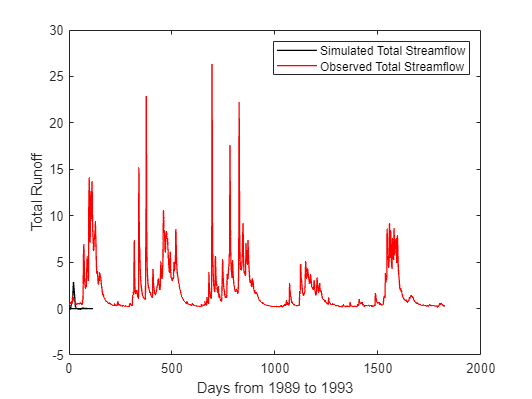

tcq=0;
tqo=0;

csnow(1,1)=300;
csoil(1,1)=100;
cs1(1,1)=3;
cs2(1,1)=10;

% simulation to determine optimal Q
for r=2:n-1
    tprec=tprec+prec(r);
    if(Temp(r)<tt)
        csnow(r,1)=csnow(r-1,1)+prec(r);
        clwater(r,1)=0;
        cpe(r,1)=PTIf(r,5);
        if(csoil(r-1,1)>cpwp)
            cea(r,1)=cpe(r,1);
        else
            cea(r,1)=cpe(r,1)*(csoil(r-1,1)/cpwp);
        end
        cdq(r,1)=clwater(r)*((csoil(r-1,1)/cfc)^cbeta);
        csoil(r,1)=csoil(r-1,1)+clwater(r,1)-cdq(r,1)-cea(r,1);
        cs1(r,1)=cs1(r-1,1)+cdq(r,1)-(max(0,cs1(r-1,1)-cl)*ck0)-(cs1(r-1,1)*ck1)-(cs1(r-1,1)*ckp);
        cs2(r,1)=cs2(r-1,1)+(cs1(r-1,1)*ckp)-cs2(r-1,1)*ck2;
        cq(r,1)=(max(0,cs1(r-1,1)-cl))*ck0+(cs1(r,1)*ck1)+(cs2(r,1)*ck2);
        cqm(r,1)=cq(r,1);
        cq_mf(r,1)=(max(0,cs1(r-1,1)-cl))*ck0+(cs1(r,1)*ck1);
        cq_ms(r,1)=(cs2(r,1)*ck2);
        cqs(r,1)=((qo(r,1)-cqm(r,1))^2);
        cqms(r,1)=((qo(r,1)-aq)^2);
    else
        csnow(r,1)=max(csnow(r-1,1)-cd*(Temp(r)-tt),0);
        clwater(r,1)=prec(r)+min(csnow(r-1,1),cd*(Temp(r)-tt));
        cpe(r,1)=PTIf(r,5);
        if(csoil(r-1,1)>cpwp)
            cea(r,1)=cpe(r,1);
        else
            cea(r,1)=cpe(r,1)*(csoil(r-1,1)/cpwp);
        end
        cdq(r,1)=clwater(r)*((csoil(r-1,1)/cfc)^cbeta);
        csoil(r,1)=csoil(r-1,1)+clwater(r,1)-cdq(r,1)-cea(r,1);
        cs1(r,1)=cs1(r-1,1)+cdq(r,1)-(max(0,cs1(r-1,1)-cl)*ck0)-(cs1(r-1,1)*ck1)-(cs1(r-1,1)*ckp);
        cs2(r,1)=cs2(r-1,1)+(cs1(r-1,1)*ckp)-cs2(r-1,1)*ck2;
        cq(r,1)=(max(0,cs1(r-1,1)-cl))*ck0+(cs1(r,1)*ck1)+(cs2(r,1)*ck2);
        cqm(r,1)=cq(r,1);
        cq_mf(r,1)=(max(0,cs1(r-1,1)-cl))*ck0+(cs1(r,1)*ck1);
        cq_ms(r,1)=(cs2(r,1)*ck2);
        cqs(r,1)=((qo(r,1)-cqm(r,1))^2);
        cqms(r,1)=((qo(r,1)-aq)^2);
    end
    tea1=tea1+cea(r,1);
    tcq=tcq+cqm(r,1);
end
% end of simulation
for z=2:n-1
    if cqm(z,1)<1
        cqm(z,1)=cqm(z,1)+0.2;
    %elseif cqm(z,1)>20
       % cqm(z,1)=(cqm(z,1)-20)*1.7+20;
    else
        cqm(z,1)=cqm(z,1);
    end
end
e1=qo-cqm;% calculating difference between q observed and q measured
cnse=1-(sum(e1.^2))/(sum((qo-aq).^2));
tdis=tprec-tea1;
reg1=corr(cqm,qo);
bias=((tcq-mqo)/mqo)*100;

%Set the results
result.snow=csnow;
result.lwater=clwater;
result.soil=csoil;
result.dq=cdq;
result.s1=cs1;
result.pe=cpe;
result.ea=cea;
result.s2=cs2;
result.qsim=cq;
result.correlation=reg1;
result.nash=cnse;
result.mp=[cd;cfc;cbeta;cc;ck0;cl;ck1;ck2;ckp;cpwp];


figure;
plot(cqm,'k-','linewidth',1);
hold on
plot(qo,'r','linewidth',1);
hold off
h = legend('Simulated Total Streamflow','Observed Total Streamflow');
set(h,'Interpreter','none')
xlabel('Days from 1989 to 1993');
ylabel('Total Runoff');

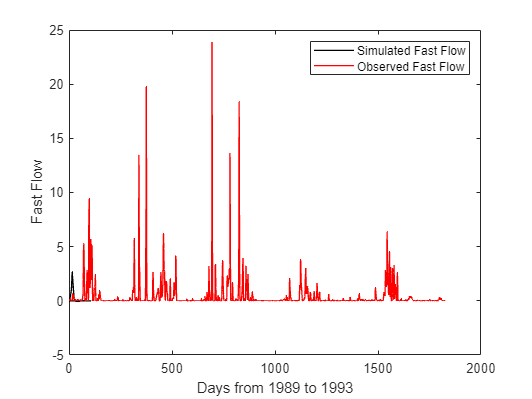



% plot observed and simulated fast flows
figure;
plot(cq_mf*0.95,'k-','linewidth',1);
hold on
plot(qf0,'r','linewidth',1);
hold off
legend('Simulated Fast Flow','Observed Fast Flow');
xlabel('Days from 1989 to 1993');
ylabel('Fast Flow');

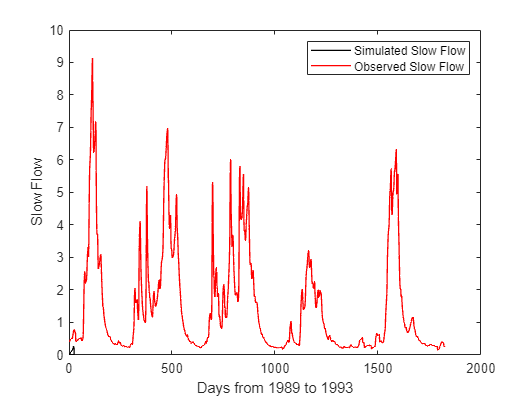


% plot observed and simulated slow flows
figure;
plot(cq_ms*4.4,'k-','linewidth',1);
hold on
plot(qs0,'r','linewidth',1);
hold off
legend('Simulated Slow Flow','Observed Slow Flow');
xlabel('Days from 1989 to 1993');
ylabel('Slow Flow');


Qsim=cqm

Qsim = 1.0e+02 *

   0.0000 + 0.0000i
   0.0056 + 0.0000i
   0.0055 + 0.0000i
   0.0054 + 0.0000i
   0.0054 + 0.0000i
   0.0053 + 0.0000i
   0.0052 + 0.0000i
   0.0051 + 0.0000i
   0.0050 + 0.0000i
   0.0050 + 0.0000i


cnse

cnse = -2.9485 - 0.0171i